# Método del Descenso del Gradiente

**Equipo Laplace**

A continuación se muestra el algoritmo de descenso del gradiente para la busqueda de mínimos locales de una función de dos variables desarrollado para la Situación Problema 'Redes Neuronales y Ecuaciones Diferenciales' de la materia MA1033.

El código a continuación esta descompuesto en secciones explicadas aumentar la fácilidad de uso del mismo.

### **Variables a Modificar**

En la presente sección aquellas lineas con comentarios corresponden a los parámetros del algoritmo los cuales pueden ser modificados por el usuario segun su gusto y conveniencia, los cuales estan despompuestos en dos grandes secciones: cálculo del mínimo de la función a partir del descenso de gradiente y graficación de los resultados.

Se inicia con la declaración de x e y como variables simbólicas para que la declaración de la función sea de la misma forma.

syms x y

#### Variables para el cálculo de mínimos a partir del descenso del gradiente

Las variables mostradas a continuación modifican los resultados obtenidos por el algoritmo en base a los parámetros escogidos por el usuario.

dx = 0.01;                                  %Paso del descenso.
max_ciclos = 1000000;                       %Limite máximo de ciclos.
tol = 1*10^-6;                              %Tolerancia de la diferencia entre puntos para declarar el mínimo local como hallado.
x_0 = 5;                                    %Posición inicial de busqueda en X.
y_0 = -5;                                   %Posicion inicial de busqueda en Y.
F = x^2+y^2                                 %Declaración de la función.

$$F = x^{2}+y^{2}$$


%F = (x^2+y-11)^2+(x+y^2-7)^2               
%Declaración de la función indicada en el inciso 3 de la métodologia de la Situación Problema.

#### Variables para la gráficación de la función y el punto cálculado

Las variables mostradas a continuación (si bien no son necesarias para hallar el mínimo local de una función a partir de una posición inicial) son auxiliares para visualizar tanto la función con la que se esta trabajando como el resultado obtenido.

lim = 10;                                   %Limite de la graficación en X, Y (lim>0)
[X,Y] = meshgrid(-lim:0.25:lim ,-lim:0.25:lim);
Z = X.^2+Y.^2;                              %Declaración de la función para graficación.


%Z = (X.^2+Y-11)^2+(X+Y.^2-7)^2;
%Declaración de la función indicada en el inciso 3 de la métodologia de la Situación Problema.

### Preparación para el algoritmo del Descenso del Gradiente

A continuación se declaran los valores iniciales como el valor de la posición actual en sus respectivos ejes y se inicializan las variables adicionales del contador de ciclos, posiciónes futuras y variables lógicas que determinan la condición de paro del ciclo.

x_cur = x_0;                                %Posicion actual en X.
x_new = 0;                                  %Posicion nueva en X.
y_cur = y_0;                                %Posicion actual en Y.
y_new = 0;                                  %Posicion nueva en Y.

count = 0;                                  %Cuenta de ciclos.

found = false;                              %Variable lógica: Indica si la diferencia entre posiciones indica si se ha llegado a la intersección.
max_reached = false;                        %Variable lógica: Indica si se ha llegado al número máximo de ciclos declarados.

Cálculo del gradiente para obtener las derivadas parciales con respecto a X e Y en base a las variables simbolicas.

Declaración de `grad` como una función de parametros x e y; esta función es empleada para hacer uso de las derivadas parciales originales y calcular el gradiente en la posición actual `(x_cur, y_cur) `dentro del ciclo del algoritmo.

grad_f = gradient(F, [x, y]);
grad = matlabFunction(grad_f, 'Vars', {x, y});

### Ciclo del Descenso del Gradiente

El ciclo corresponde a la sección mas importante del algoritmo del descenso de gradiente ya que en este se llevan a cabo los cálculos que permiten actualizar las posiciones `(x_cur, y_cur)` en dirección opuesta al gradiente de la función evaluada en este punto, lo que permite segun el paso redigirir el punto hacia el mínimo local más cercano al punto de partida; de igual forma, se evaluan las condiciones de paro en cada ciclo de modo que el algoritmo:

- Se detenga si el número de ciclos es mayor o igual al número de ciclos límite establecidos por el usuario.

- Se detenga si la diferencia entre el punto anterior y el nuevo punto cálculado es menor a una tolerancia en cocreto definida por el usuario.

while (~found && ~max_reached)
    %Cálculo del gradiente en base al punto actual.
    g = grad(x_cur, y_cur);
    gx = g(1);
    gy = g(2);
  

#### Cálculo del siguiente punto en base al descenso del gradiente


$$x_{n+1} =x_n -h\;\nabla \;f\left(x_n \right)$$



$$y_{n+1} =y_n -h\;\nabla \;f\left(y_n \right)$$


El cambio en el eje que se tiene en el siguiente tiempo es igual a la resta de la posición anterior menos el paso multiplicado por el gradiente de la función evaluado en base al punto actual; dando como resultado un movimiento en la dirección opuesta al gradiente de la función.

    x_new = x_cur - dx*gx;

Numero de ciclos = 589

    y_new = y_cur - dx*gy;

    %Incremento del contador de ciclos
    count = count+1;

    %Condición de paro: Número de ciclos excedido

Punto donde se paso la tolerancia = (0.0000, -0.0000)

    if(count>= max_ciclos)
        max_reached = true;
    end

    %Condición de paro: Diferencia entre puntos menor a la tolerancia
    %declarada
    if(norm([x_new; y_new] - [x_cur; y_cur])< tol)
        found = true;
    end

    %Actualización de las posiciones actuales.
    x_cur = x_new;
    y_cur = y_new;
end

### Impresión y graficación de los resultados

Impresión de los resultados obtenidos en base a la condición de paro empleada.

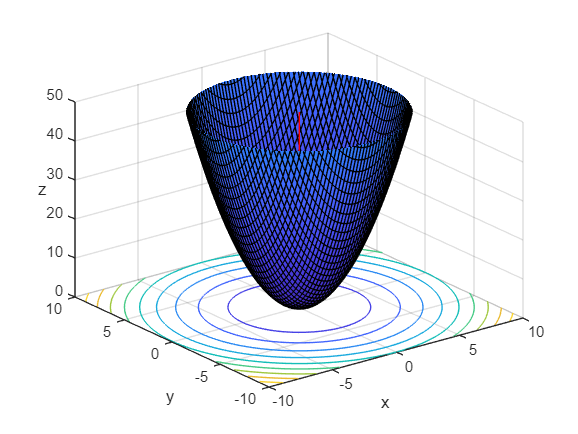

fprintf('Numero de ciclos = %.0f',count)
if (max_reached)
    fprintf('Punto donde se excedio el número de ciclos = (%.4f, %.4f)',x_new, y_new);
end

if(found)
    fprintf('Punto donde se paso la tolerancia = (%.4f, %.4f)',x_new, y_new);
end

Graficación tridimensional de la función declarada (esta debe ser la misma que la función para el cálculo del mínimo local) en base a los limites establecidos y gráficación de una linea sobre la misma donde se haya el punto obtenido en base al algoritmo del descenso del gradiente.

%Graficación tridimensional de la función
surfc(X,Y,Z)
hold on

%Declaración de las variables para la graficación de la linea.
z_g = -500000:0.5:500000;
x_g = x_cur * ones(size(z_g));
y_g = y_cur * ones(size(z_g));

%Graficación de la linea
plot3(x_g, y_g, z_g,'r')

%Especificaciónes visuales de la gráficación
axis([-lim lim -lim lim 0 50])
xlabel('x')
ylabel('y')
zlabel('z','Rotation',0)